# Example of Functional Sensor to Segment Calibration using Xsens and Magnetic-Free-Quaternion-Based data

S. A. Salinas, M. Berjis, K. Grolinger, and A. L. Trejos, Estimating Thorax and Shoulder Motion Using Magnetic-Free Quaternion-Based Functional Sensor-to-Segment Calibration, International Conference on Rehabilitation Robotics (ICORR), Chicago, USA, May 2025.

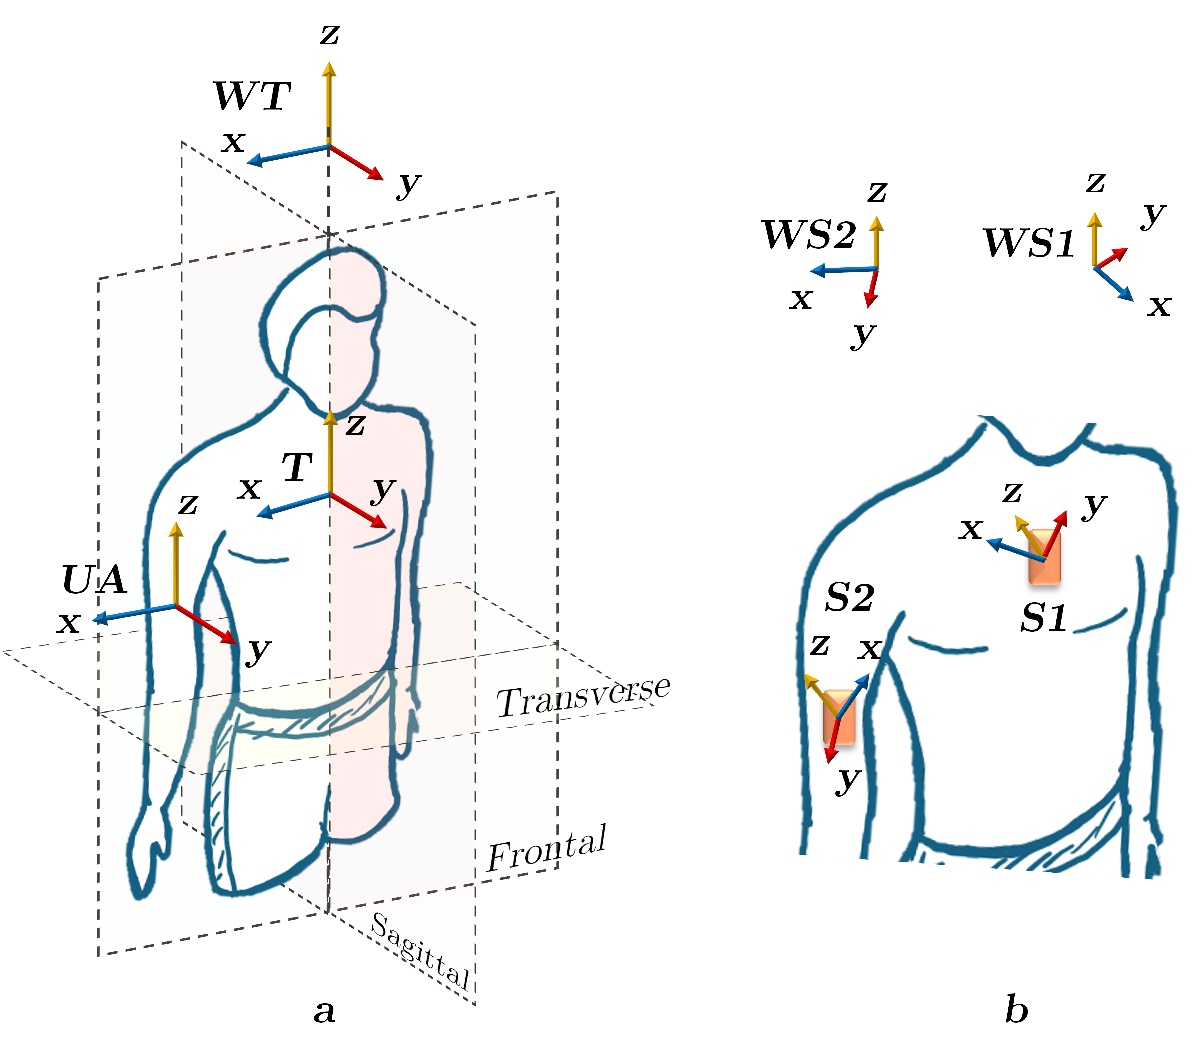

The calibration is used in this example for thorax and shoulder orientations. 

The thorax is the first segment of interest with one inertial sensor attached to it. As shown in the figure, the coordinate system (T), linked to the thorax, changes its orientation as a function of the thorax motion. Its z axis is the inferior--superior axis perpendicular to the transverse plane, the y axis is the anterior--posterior axis perpendicular to frontal plane, and the x axis is the medio--lateral axis perpendicular to the sagittal plane. The orientation of T is measured with respect to a global reference coordinate system of the body (WT). This reference frame corresponds to the sagittal, frontal, and transverse planes when the participant is in an initial N-pose. The vertical axis pointing up is defined as the positive z axis, the sagittal axis from the back to the front of the body is defined as the positive y axis, and the frontal axis from left to right is defined as the positive x axis. 

The IMU attached to the thorax is represented by a box with a reference coordinate system (S1). The orientation of S1 is measured by this IMU with respect to its own global reference coordinate system (WS1). 

The upper arm is the second segment. The coordinate system (UA) linked to the upper arm changes its orientation as a function of the upper arm motion. Its z axis corresponds to the shoulder internal--external rotation axis, the y axis coincides with the shoulder abduction--adduction axis, and the x axis with the shoulder flexion--extension axis. 

The IMU attached to the upper arm is represented by a box with a reference coordinate system (S2). The orientation of S2 is measured by this IMU with respect to its own global reference coordinate system (WS2). It is important to note that WS1 and WS2 have different orientations. However, the constant rotation between the global reference coordinate systems of the two inertial sensors is a rotation about their z axes.  

Two set of sensors were used, the commercial Xsens and a prototype based on the BNO055 sensor. Orientation data were simultaneously collected by both systems while the participant stood in a static N-pose for ten seconds, followed by ten functional movement repetitions of the thorax or upper arm. The thorax movements were forward flexions and lateral flexion--extension; whereas, the upper arm movements were consequences of shoulder flexion--extension and shoulder abduction--adduction.

clear 
close all
load("qAll.mat")

Unable to resolve the name 'qAll.Properties.SampleRate'.

### Thorax

%plot(qSquats.Time, dist(qSquats{:,"Var1_qS1"},qSquats{1,"Var1_qS1"}))
intervX = {timerange(seconds(1),seconds(6));  % X axis of body    Squats           
        timerange(qSquats.Time(1),qSquats.Time(end));
        };
intervY = {timerange(seconds(0),seconds(4));    % Y axis of body   Sides
        timerange(qSides.Time(1),qSides.Time(end));
        };
axisMov = { {"x", "y"}, ... %Xsens
            {"x", "y"}};%IMU
[BqS, WBqWS, errWBqWS] = ...
            S2SCalibT(qAll(:,["Var1_qX1","Var1_qS1"]), intervX, intervY, axisMov)

errWBqWSideal =     0.1236    0.1236    0.0858    0.0854    0.0917    0.0598


errWBqWSideal =     0.1110    0.1109    0.1108    0.0141    0.0836    0.0562


BqS = 1×2 quaternion array
     0.56354 - 0.39556i - 0.47315j - 0.54962k    -0.59689 +  0.4218i + 0.34859j + 0.58677k


WBqWS = 1×2 quaternion array
     0.67237 +       0i +       0j - 0.74022k    -0.98965 +       0i +       0j - 0.14349k


errWBqWS =     0.0598    0.0141



% WBqT_Sq = WBqWS .* qAll{tSquats,["Var1_qX1","Var1_qS1"]} .* conj(BqS); 
% WBqT_Si = WBqWS .* qAll{tSides,["Var1_qX1","Var1_qS1"]} .* conj(BqS); 

WBqT = timetable(qAll.Time);
WBqT{:,1:2} = WBqWS .* qAll{:,["Var1_qX1","Var1_qS1"]} .* conj(BqS);

TqS1 = BqS;
WBqW1 = WBqWS;

`BqS = 1×2 quaternion array`

`     0.55996 - 0.37112i -  0.4765j - 0.56716k     0.58259 - 0.42252i - 0.35236j - 0.59826k`

`WBqWS = 1×2 quaternion array`

`     0.67559 +       0i +       0j - 0.73728k      -0.992 +       0i +       0j -  0.1262k`

`errWBqWS = ``1×2`

`    0.0589    0.0357`

### Functional mov Sensor 3: Upper Arm (SAME PROCEDURE AS TORSO) 


intervY = {timerange(seconds(492),seconds(496));  % Y axis of body    Abd
        timerange(seconds(503),seconds(510));
        };
intervX = {timerange(seconds(374),seconds(378));    % X axis of body   FE
        timerange(seconds(386),seconds(400)); 
        };
axisMov = { {"x", "-y"}, ... %Xsens
            {"-x", "y"}};%IMU
[UAqS2, WBqW2, errWBqW2] = S2SCalibT4( qAll(:,["Var1_qX3","Var1_qS3"]), intervX, intervY, axisMov)

errWBqWSideal =     0.7715    0.7715    0.1093    0.5410    0.5114    0.2597


errWBqWSideal =     0.6953    0.6953    0.1085    0.3592    0.4256    0.1666


UAqS2 = 1×2 quaternion array
     -0.10384 -  0.70082i + 0.034239j -  0.70491k      0.61337 +  0.34727i -  0.64006j +  0.30577k


WBqW2 = 1×2 quaternion array
     0.65606 +       0i +       0j - 0.75471k     0.76041 +       0i +       0j - 0.64945k


errWBqW2 =     0.1093    0.1085


                                       
rad2deg(dist(WBqW1.conj .* WBqW2,quaternion.ones))

ans =     2.5000   97.5000



TqUA = timetable(qAll.Time);
TqUA{:,1:2} = TqS1 .* conj(qAll{:,["Var1_qX1","Var1_qS1"]}) .* WBqW1.conj .* WBqW2 .* ...
                           qAll{:,["Var1_qX3","Var1_qS3"]}  .* conj(UAqS2);

WBqUA = timetable(qAll.Time);
WBqUA{:,1:2} = WBqW2 .* qAll{:,["Var1_qX3","Var1_qS3"]} .* conj(UAqS2);

### Functional mov Sensor 3: Upper Arm


intervY = {timerange(seconds(492),seconds(496));  % Y axis of body    Abd
        timerange(seconds(503),seconds(510));
        };
intervX = {timerange(seconds(374),seconds(378));    % X axis of body   FE
        timerange(seconds(386),seconds(400)); 
        };
axisMov = { {"x", "-y"}, ... %Xsens
            {"-x", "y"}};%IMU
[UAqS2, W1qW2, errW1qW2] = S2SCalibUA3( qAll(:,["Var1_qX3","Var1_qS3"]), intervX, intervY, axisMov,...
                                        qAll(:,["Var1_qX1","Var1_qS1"]), TqS1, WBqW1)

errW1qW2ideal =     0.7594    0.7641    0.0977    0.5354    0.7613    0.2542    0.5021


errW1qW2ideal =     0.7391    0.7109    0.1565    0.3685    0.7276    0.1818    0.4552


UAqS2 = 1×2 quaternion array
    -0.097156 -  0.70505i + 0.022846j -  0.70209k     -0.59357 -  0.34839i +  0.65173j -  0.31865k


W1qW2 = 1×2 quaternion array
     0.99991 +       0i +       0j - 0.01309k     0.64612 +       0i +       0j - 0.76323k


errW1qW2 =     0.0977    0.1565


rad2deg(dist(W1qW2,quaternion.ones))

ans =     1.5000   99.5000



TqUA = timetable(qAll.Time);
TqUA{:,1:2} = TqS1 .* conj(qAll{:,["Var1_qX1","Var1_qS1"]}) .* W1qW2 .* ...
                           qAll{:,["Var1_qX3","Var1_qS3"]}  .* conj(UAqS2);

`UAqS2 = 1×2 quaternion array`

`     -0.15365 -   0.6955i - 0.068539j -  0.69855k      0.63093 +  0.33913i -  0.59144j +  0.37028k`

`W1qW2 = 1×2 quaternion array`

`     0.99991 +       0i +       0j - 0.01309k       0.682 +       0i +       0j - 0.73135k`

`errW1qW2 = ``1×2`

`    0.2253    0.2016`

## Estimations error

- Torso orientation

texperim = tSquats;
texperim = tSides;
texperim = tShFE;
%texperim = tShAb;

ErrT = rad2deg(dist(WBqT{texperim,"Var1"},WBqT{texperim,"Var2"}));
%plot(WBqT.Time(texperim),ErrT), 
rmseT = rms(ErrT)

rmseT = 4.1640

%MAET = mean(abs(ErrT))
stdeT = std(ErrT)

stdeT = 0.6443


ErrSh= rad2deg(dist(TqUA{texperim,"Var1"},TqUA{texperim,"Var2"}));
%plot(TqUA.Time(texperim),ErrSh)
rmseSh = rms(ErrSh)

rmseSh = 7.8599

%MAESh = mean(abs(ErrSh))
stdeSh = std(ErrSh)

stdeSh = 3.6884

## Angles of movement

### Torso angles

tTest = tSides;
tTest = tSquats;
TtTest = WBqT{tTest,:};
figtime = 0:1/60:(length(TtTest)-1)/60;
%T1qT = conj(TtTest(1,:)) .* TtTest;

%initialization
TRot0 = zeros(length(figtime),3);
errorT = [];

for k =1:2 %number of systems: Xsens, IMUs
    TRot = eulerd(TtTest(:,k),'XYZ','frame');
%     figure, plot(figtime, TRot); 
%     legend("FE","LateralFE","Rotation",Location="best"), grid on, 
%     ylabel("Angle(deg)"), xlabel("time(s)")
%     spams = peak2peak(TRot);
%     ylim([-100 20])
    errorT = TRot -TRot0;
    TRot0 = TRot;
end
rms(errorT)

### Shoulder angles

k = 1

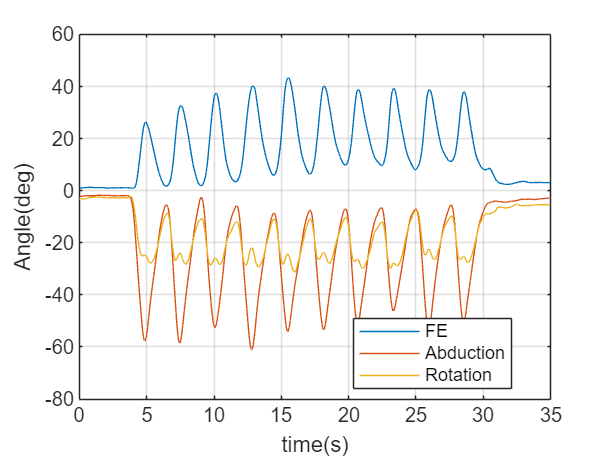

k = 2

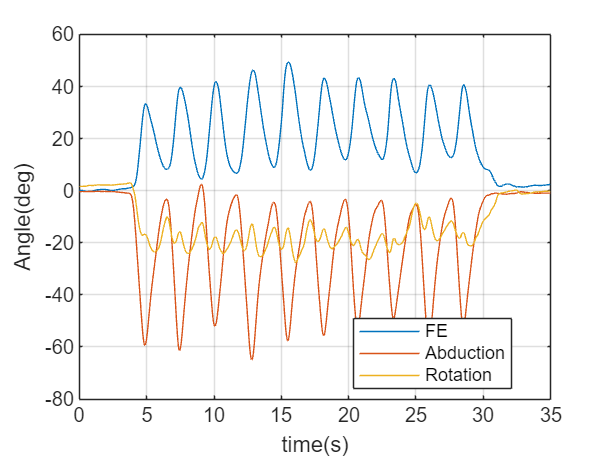

tTest = tShAb;
%tTest = tShFE;
ShtTest = TqUA{tTest,:};
figtime = 0:1/Fs:(length(ShtTest)-1)/Fs;
%T1qT = conj(TtTest(1,:)) .* TtTest;

%initialization
ShRot0 = zeros(length(figtime),3);
errorSh = [];

for k =1:2 %number of systems: Xsens, IMUs

    %My approach
    ShRot = ShAngles(ShtTest(:,k));
    k
    figure, plot(figtime, ShRot); 
    legend("FE","Abduction","Rotation",Location="best"), grid on,
    %legend("Plane","Elevation","Rotation",Location="best"), grid on,
    ylabel("Angle(deg)"), xlabel("time(s)")
    spams = peak2peak(ShRot);
    %ylim([-90 60])  %AA
    errorSh = ShRot -ShRot0;
    ShRot0 = ShRot;
end

rms(errorSh)

### Thorax angle errors

Fsize = 12;
%Fname = 'Helvetica';% 
Fname = 'Times New Roman';

TRotX = [eulerd(WBqT{tSquats,1},'XYZ','frame');eulerd(WBqT{tSides,1},'XYZ','frame')];
TRotS = [eulerd(WBqT{tSquats,2},'XYZ','frame');eulerd(WBqT{tSides,2},'XYZ','frame')];
figtime = 0:1/Fs:(length(TRotS)-1)/Fs;

% % filtering
Fc = 6; %Hz
[b,a] = butter(6,Fc/(Fs/2)); %6th order
TRotX = filter(b,a,TRotX);
TRotS = filter(b,a,TRotS);

%Error
errorT = TRotX-TRotS;
rms(errorT)

ans =     3.8823    1.2792    1.9332


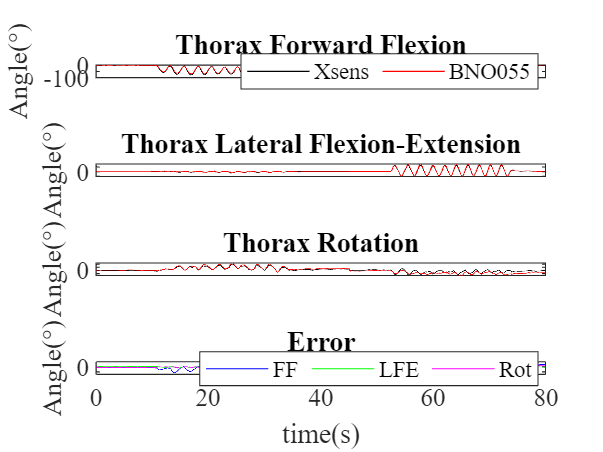


figure, 
subplot(4,1,1)
plot(figtime, TRotX(:,1),'k',...
     figtime, TRotS(:,1),'r');
legend("Xsens","BNO055",Location="best",Orientation="horizontal"), %grid on,
ylabel("Angle(" +char(176)+ ")"),
title("Thorax Forward Flexion")%xlabel("time(s)")
ax = gca; ax.FontName = Fname; ax.FontSize = Fsize; ax.XTick=[];

subplot(4,1,2)
plot(figtime, TRotX(:,2),'k',...
     figtime, TRotS(:,2),'r');
%legend("Xsens","BNO055",Location="best"), %grid on,
ylabel("Angle(" +char(176)+ ")"),
title("Thorax Lateral Flexion-Extension")
ax = gca; ax.FontName = Fname; ax.FontSize = Fsize; ax.XTick=[];

subplot(4,1,3)
plot(figtime, TRotX(:,3),'k',...
     figtime, TRotS(:,3),'r');
%legend("Xsens","BNO055",Location="best"), %grid on,
ylabel("Angle(" +char(176)+ ")"),
title("Thorax Rotation")
ax = gca; ax.FontName = Fname; ax.FontSize = Fsize; ax.XTick=[];

subplot(4,1,4)
plot(figtime, errorT(:,1),'b',...
     figtime, errorT(:,2),"g", ...
     figtime, errorT(:,3),"m");
legend("FF","LFE","Rot",Location="best",Orientation="horizontal"),% grid on,
ylabel("Angle(" +char(176)+ ")"),
title("Error"), xlabel("time(s)")
ylim([-15 10])
ax = gca; ax.FontName = Fname; ax.FontSize = Fsize;

### Shoulder angle errors

ShRotX = [ShAngles(TqUA{tShFE,1});ShAngles(TqUA{tShAb,1})];
ShRotS = [ShAngles(TqUA{tShFE,2});ShAngles(TqUA{tShAb,2})];
figtime = 0:1/60:(length(ShRotS)-1)/60;
% % filtering
Fc = 6; %Hz
[b,a] = butter(6,Fc/(Fs/2)); %6th order
ShRotX = filter(b,a,ShRotX);
ShRotS = filter(b,a,ShRotS);

%Error
errorSh = ShRotX-ShRotS;
rms(errorSh)

ans =     4.1056    4.0676    5.1387


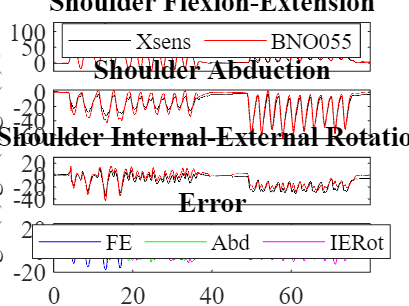


figure, 
subplot(4,1,1)
plot(figtime, ShRotX(:,1),'k',...
     figtime, ShRotS(:,1),'r');
legend("Xsens","BNO055",Location="best", Orientation="horizontal"), 
%grid on,
ylabel("Angle(" +char(176)+ ")"),
title("Shoulder Flexion-Extension")%xlabel("time(s)")
ax = gca; ax.FontName = Fname; ax.FontSize = Fsize; ax.XTick=[];

subplot(4,1,2)
plot(figtime, ShRotX(:,2),'k',...
     figtime, ShRotS(:,2),'r');
%legend("Xsens","BNO055",Location="best"), grid on,
ylabel("Angle(" +char(176)+ ")"), title("Shoulder Abduction")
ax = gca; ax.FontName = Fname; ax.FontSize = Fsize; ax.XTick=[];

subplot(4,1,3)
plot(figtime, ShRotX(:,3),'k',...
     figtime, ShRotS(:,3),'r');
%legend("Xsens","BNO055",Location="best"), grid on,
ylabel("Angle(" +char(176)+ ")"),
title("Shoulder Internal-External Rotation")
ylim([-50 30])
ax = gca; ax.FontName = Fname; ax.FontSize = Fsize; ax.XTick=[];

subplot(4,1,4)
plot(figtime, errorSh(:,1),'b',...
     figtime, errorSh(:,2),"g", ...
     figtime, errorSh(:,3),"m");
legend("FE","Abd","IERot",Location="best",Orientation="horizontal"), %grid on,
ylabel("Angle(" +char(176)+ ")"),
title("Error"), xlabel("time(s)")
ylim([-20 25])
ax = gca; ax.FontName = Fname; ax.FontSize = Fsize;

### Shoulder angles (ISB and modifications)

k = 1

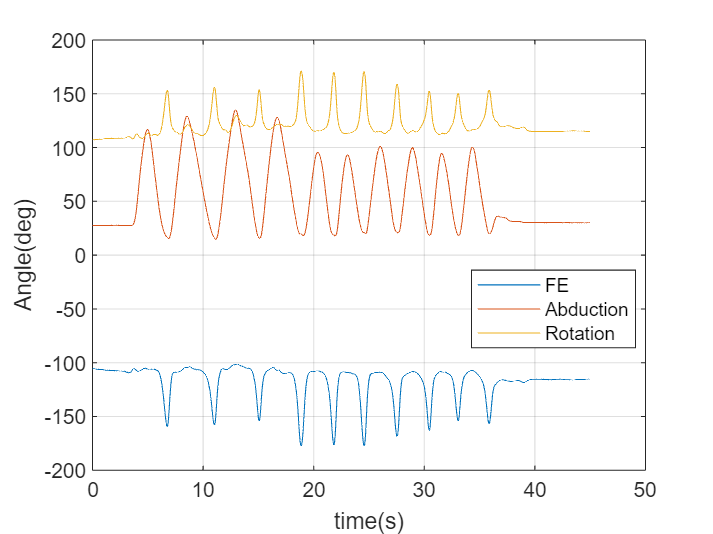

k = 2

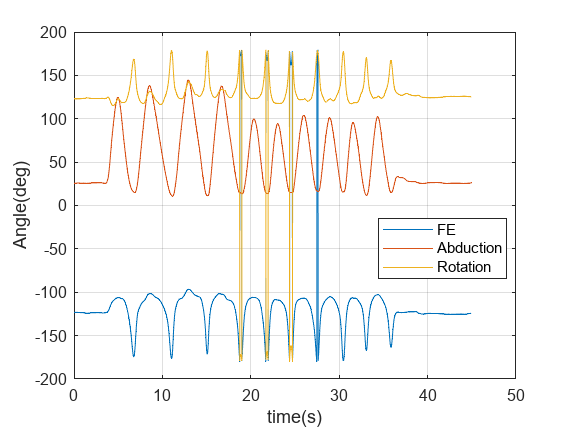

tTest = tShAb;
tTest = tShFE;
ShtTest = TqUA{tTest,:};
figtime = 0:1/60:(length(ShtTest)-1)/60;
%T1qT = conj(TtTest(1,:)) .* TtTest;
for k =1:2 %number of systems: Xsens, IMUs

    %Following the ISB recommendations: (NO A GOOD OUTPUT)
%     initialAng = eulerd(ShtTest(1,k),'ZYZ','frame');
%     ShRot = rad2deg((euler(conj(ShtTest(1,k)) * ShtTest(:,k),'ZYZ','frame')));
%     ShRot = ShRot + initialAng;

    ShRot = rad2deg((euler(ShtTest(:,k),'ZYZ','frame')));
   
    k
    figure, plot(figtime, ShRot); 
    legend("FE","Abduction","Rotation",Location="best"), grid on,
    %legend("Plane","Elevation","Rotation",Location="best"), grid on,
    ylabel("Angle(deg)"), xlabel("time(s)")
    spams = peak2peak(ShRot);
    %ylim([-90 60])  %AA
end

## Animation of Actual Motion

%timeframe = tShAb;
timeframe = tShFE;
%timeframe= tShSc2;
%timeframe= tShROMHorFE;
%timeframe= tShROMAb;
%timeframe = timerange(seconds(430),seconds(460)) %S1 of Xsens error.
%timeframe = timerange(seconds(765),seconds(775)) %S1 y S3 Xsens not sinchronized in time
%timeframe = timerange(seconds(902),seconds(920)) %S1 IMUs discalibrated
system =1; %1:Xsens  2:IMUs
% clavicle length
L1 = 1;
% Upper Arm length
L2 = 1.8;
% Distances 
WBpT = [0;0;0];
TpSh = [L1;0;0];
ShpUA = [0;0;-L2];
% names
names = ["Torso", "Shoulder", "UpperArm"];
figure,
p = poseanim([WBqT{timeframe,system} WBqUA{timeframe,system} WBqUA{timeframe,system}],...
             [WBpT TpSh ShpUA], names, 0.0005);


%Seg = WBqWS(2)*qAll{tSquats,"Var1_qS1"} *conj(BqS(2));
Seg = WBqWS(2)*qAll{tShFE,"Var1_qS3"} *conj(BqS(2));
figure,
PoseP = poseplot(Seg(1),"ENU");  hold on;
% For a better visualization:
xlabel("x")
ylabel("y")
zlabel("z")
PoseP.Parent.YDir ="reverse";
PoseP.Parent.XDir ="reverse";
for k = 2:length(Seg)
    set(PoseP,Orientation=Seg(k))        
    pause(0.00005)
end
hold off